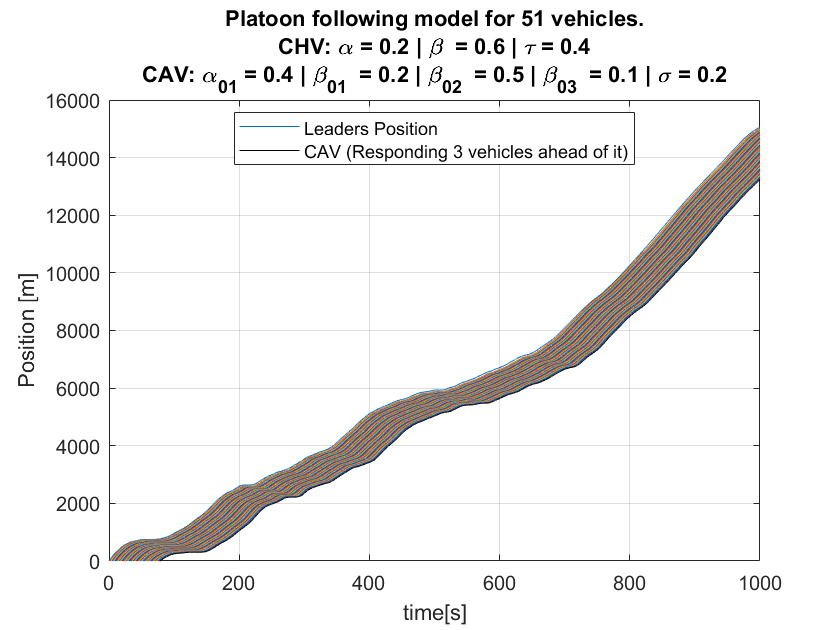

% Simulation 50 vehicles with CAV at last

clear;close all;

follow_num = 49;
vehicle_num = 51;
vehicle_length = 4;

%fixed parameters for CAV
hstop = 5;
hgo = 55;
vmax = 40;

hstar_chv = 42.5;
vstar_chv = 30;

%parameters for CAV
alpha01 = 0.4;
beta01 = 0.2;
beta02 = 0.5;
beta03 = 0.1;
kappa0 = vmax/(hgo-hstop);
sigma = 0.2;
vstar_cav = 30;
hstar_cav = hstop + vstar_cav/kappa0;

%parameters for CHVs
alphah = 0.2;
betah = 0.6;
kappah = vmax/(hgo-hstop);
tau = 0.4;

%simulation time
t0 = 0;
deltat = 0.1;
tend = 1000;
tspan = linspace(t0,tend,9017);

traffic_data = load('traffic_data_long.mat');
vLead = traffic_data.vLead';
vLead_delayed=(tspan<t0+tau).*vstar_chv+...
              (t0+tau<=tspan).*interp1(tspan,vLead,tspan-tau,'linear','extrap');
       

%for integrating leader's velocity
ic_vlead = 0;
sol_dde_vlead = dde23(@(t,y,ytau)ddefun_vlead(t,y,ytau,vLead_delayed,tspan),tau,ic_vlead,tspan);
y_vlead_position = deval(sol_dde_vlead,tspan);

%for CHV
s = 1:follow_num;
s0 = s.*(-hstar_chv-vehicle_length);
s0 = s0';
% s0 = [(-hstar_chv-vehicle_length) (-2*hstar_chv-2*vehicle_length)]'.*ones(follow_num,1);
h0 = hstar_chv*ones(follow_num,1);
vh0 = vstar_chv*ones(follow_num,1);
ic_chv = @(t)[s0 h0 vh0];
sol_chv = dde23(@(t,y,ytau)ddefun_chv(t,y,ytau,follow_num,alphah,betah,vmax,hstop,hgo,vLead,vLead_delayed,tspan,kappah),tau,ic_chv,tspan);
y_chv = deval(sol_chv,tspan);

positions = y_chv(1:follow_num,:);         
headways = y_chv(follow_num+1:2*follow_num,:);
velocities = y_chv(2*follow_num+1:end,:);

%for CAV
ic_cav = @(t)[-(follow_num*hstar_chv + hstar_cav + (follow_num+1)*vehicle_length) hstar_cav vstar_cav];
sol_cav = dde23(@(t,y,ysigma)ddefun_cav(t,y,ysigma,alpha01,beta01,beta02,beta03,kappa0,vmax,hstop,hgo,y_chv,tspan,vLead,vLead_delayed,follow_num),sigma,ic_cav,tspan);
y_cav = deval(sol_cav,tspan);

position_cav = y_cav(1,:);
headway_cav = y_cav(2,:);
velocity_cav = y_cav(3,:);

figure(1);hold on ; box on; grid on;
p1 = plot(tspan,y_vlead_position);
p2 = plot(tspan,positions);
p3 = plot(tspan,position_cav,'k');
xlabel('time[s]');
ylabel('Position [m]');
axis([0,1000,0,16000]);
title({"Platoon following model for "+vehicle_num+ " vehicles.",...
       "CHV: \alpha = "+alphah+" | \beta  = "+betah+" | \tau = "+tau ,...
       "CAV: \alpha_{01} = "+alpha01+" | \beta_{01}  = "+beta01+" | \beta_{02}  = "+beta02+" | \beta_{03}  = "+beta03+" | \sigma = "+sigma});
legend([p1 p3],{'Leaders Position',"CAV (Responding 3 vehicles ahead of it)"},'Location',"best");

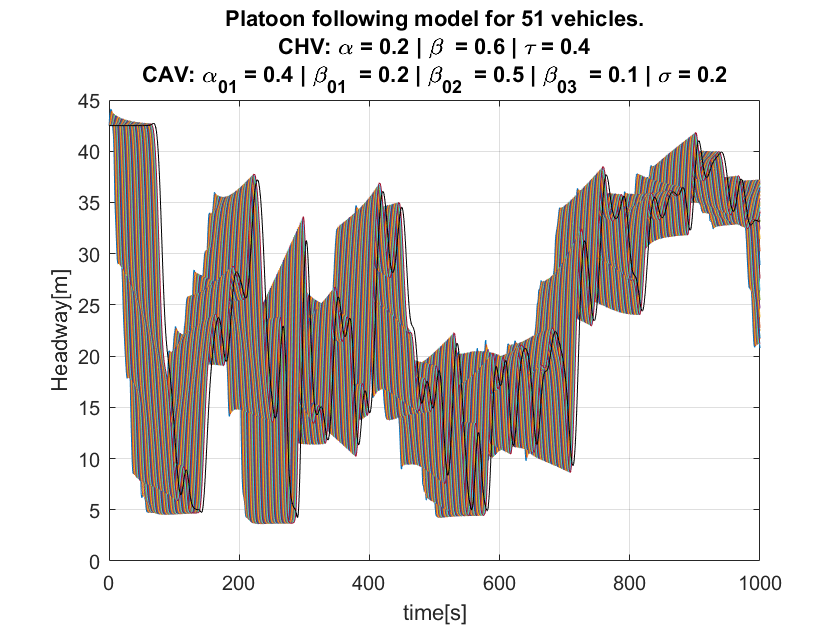


figure(2); hold on ; box on; grid on;
plot(tspan,headways);
plot(tspan,headway_cav,'k');
xlabel('time[s]');
ylabel('Headway[m]');
title({"Platoon following model for "+vehicle_num+ " vehicles.",...
       "CHV: \alpha = "+alphah+" | \beta  = "+betah+" | \tau = "+tau ,...
       "CAV: \alpha_{01} = "+alpha01+" | \beta_{01}  = "+beta01+" | \beta_{02}  = "+beta02+" | \beta_{03}  = "+beta03+" | \sigma = "+sigma});

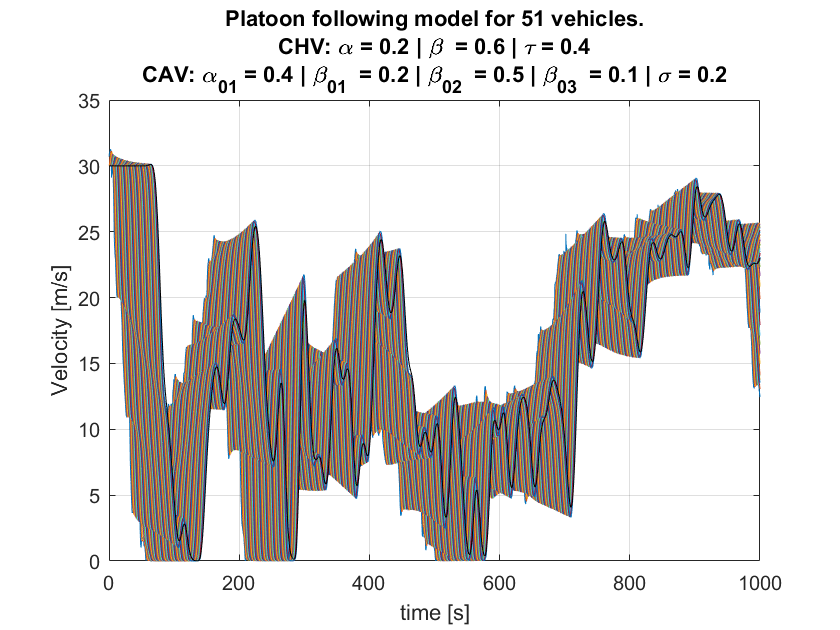



figure(3); hold on; box on; grid on;
plot(tspan,vLead);
plot(tspan,velocities);
plot(tspan,velocity_cav,'k');
xlabel('time [s]');
ylabel('Velocity [m/s]');
title({"Platoon following model for "+vehicle_num+ " vehicles.",...
       "CHV: \alpha = "+alphah+" | \beta  = "+betah+" | \tau = "+tau ,...
       "CAV: \alpha_{01} = "+alpha01+" | \beta_{01}  = "+beta01+" | \beta_{02}  = "+beta02+" | \beta_{03}  = "+beta03+" | \sigma = "+sigma});

function dydt = ddefun_vlead(t,y,ytau,vLead_delayed,tspan)
        vL_delayed = @(t)interp1(tspan,vLead_delayed,t,'linear','extrap');
        dydt = vL_delayed(t);
end
     
function dydt = ddefun_chv(t,y,ytau,follow_num,alphah,betah,vmax,hstop,hgo,vLead,vLead_delayed,tspan,kappah) 
    
    vL = @(t)interp1(tspan,vLead,t,'linear','extrap');
    vL_delayed = @(t)interp1(tspan,vLead_delayed,t,'linear','extrap');
    
    s = y(1:follow_num);
    h = y(follow_num+1:2*follow_num);
    vF = y(2*follow_num+1:end);
    vL = [vL(t);
      vF(1:follow_num-1)] ;
  
    stau = ytau(1:follow_num);
    htau = ytau(follow_num+1:2*follow_num);
    vFtau = ytau(2*follow_num+1:end);
    vLtau = [vL_delayed(t);
          vFtau(1:follow_num-1)] ;
      
    %Range Policy according to hW 7
%     Vh = (h<hstop).*0 + ((hstop<h)&(h<hgo)).*((2*hgo - hstop - htau).*(htau-hstop)*vmax/(hgo-hstop)^2) + (h>=hgo).*(vmax);
%     Vhtau = (h<hstop).*0  + ((hstop<h)&(h<hgo)).*((2*hgo - hstop - htau).*(htau-hstop)*vmax/(hgo-hstop)^2) + (h>=hgo).*(vmax);
    
    %linear range policy
    Vh = (h<hstop).*0 + ((hstop<h)&(h<hgo)).*(kappah*(h-hstop)) + (h>=hgo).*(vmax);
    Vhtau = (h<hstop).*0  + ((hstop<h)&(h<hgo)).*(kappah*(htau-hstop)) + (h>=hgo).*(vmax);

    
    dydt = [ vF  ;(vL-vF); alphah.*(Vhtau-vFtau)+betah.*(vLtau-vFtau)];

end

function dydt = ddefun_cav(t,y,ysigma,alpha01,beta01,beta02,beta03,kappa0,vmax,hstop,hgo,y_chv,tspan,vLead,vLead_delayed,follow_num)

    Vhsigma = (y(2)<hstop).*0 + ((hstop<y(2))&(y(2)<hgo)).*kappa0*(ysigma(2)-hstop) + (y(2)>=hgo).*(vmax);
    
    vLead1 = @(t)interp1(tspan,y_chv(end,:),t,'linear','extrap');
    vLead2 = @(t)interp1(tspan,y_chv(end-1,:),t,'linear','extrap');
    vLead3 = @(t)interp1(tspan,y_chv(end-2,:),t,'linear','extrap');
    
    %vL = @(t)interp1(tspan,vLead,t,'linear','extrap');
    %vL_delayed = @(t)interp1(tspan,vLead_delayed,t,'linear','extrap');
    
    dydt(1) = y(3);
    dydt(2) = vLead1(t) - y(3);
    dydt(3) = alpha01*Vhsigma - (alpha01 + beta01 + beta02 + beta03).*ysigma(3) +...
              beta01.*vLead1(t) + beta02.*vLead2(t) + beta03.*vLead3(t) ; 
    
    dydt = dydt';
end




